clc;close all;clear;

# 取反矢量的给定距离约束的端点坐标解算方法

## Step.1 导入相机星光定姿光轴矢量数据

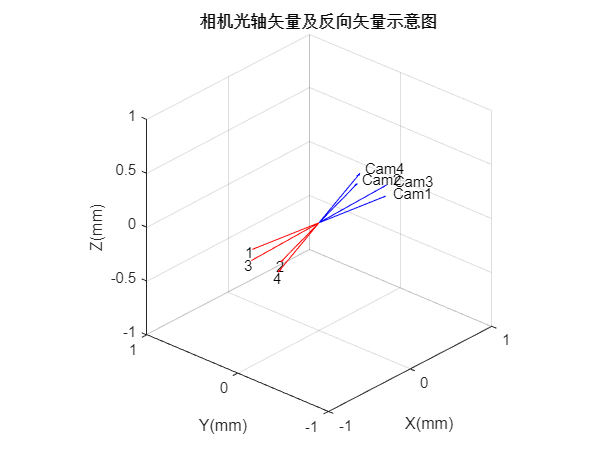


camnum=4;%四台相机

A=[-0.00743315075508644	-0.822069587759869	0.569338511915512
 -0.212031193941237	-0.658226663884978	0.722343707487445
 0.0669664113878995	-0.768261266127595	0.636624007333882
 -0.125489147751819	-0.614238634036690	0.779078541774360];

o=[0,0,0];
for j=1:camnum
figure(1)

quiver3(o(1),o(1),o(1),A(j,1),A(j,2),A(j,3),'Color','b');hold on; axis equal;

view([-48.11 28.00])
title("相机光轴矢量及反向矢量示意图")
xlabel("X(mm)")
ylabel("Y(mm)")
zlabel("Z(mm)")
text(A(j,1),A(j,2),A(j,3),['Cam',num2str(j) ]);hold on;axis equal;
B=-A;%矢量取反

quiver3(o(1),o(1),o(1),B(j,1),B(j,2),B(j,3),'Color','r');hold on; axis equal;
text(B(j,1),B(j,2),B(j,3),[num2str(j) ]);hold on;axis equal;
xlim([-1 1])
ylim([-1 1])
zlim([-1 1])
end

## Step.2 点向式空间直线方程原理


% (x-x0)/m = (y-y0)/n = (z-z0)/p;
% (y-y0)/n = (z-z0)/p;
% (x-x0)/m = (y-y0)/n;
% (x-x0)/m = (z-z0)/p;
% sqrt(x^2+y^2+z^2)=Dis;


## Step.3 点向式空间直线方程组解算

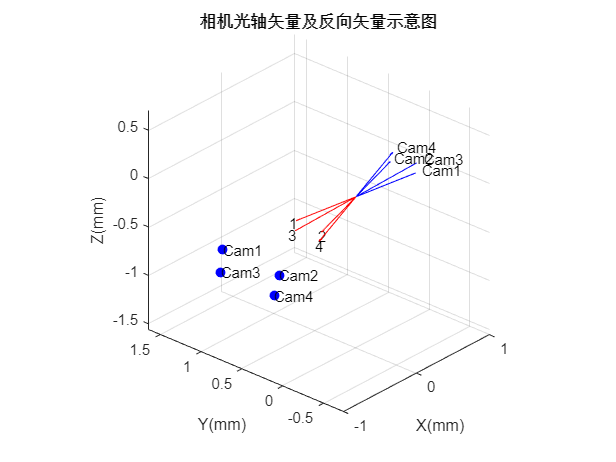


for i=1:camnum
syms x y z
eqns = [x/B(i,1) == y/B(i,2), x/B(i,1) == z/B(i,3),y/B(i,2) == z/B(i,3),(x^2+y^2+z^2)^0.5==2];%方程生成及距离约束
vars = [x y z];
[x, y, z] = solve(eqns, vars);
%==========保证解算向量的象限与所在矢量象限一致==========
if x(1,1)*B(i,1)>0
    a=x(1,1);
else
    a=x(2,1);
end

if y(1,1)*B(i,2)>0
    b=y(1,1);
else
    b=y(2,1);
end

if z(1,1)*B(i,3)>0
    c=z(1,1);
else
    c=z(2,1);
end
%====================================================
figure(1)
plot3(a,b,c,'b.','Markersize',20);hold on;axis equal;
text(a,b,c,['Cam',num2str(i) ]);hold on;axis equal;
xlim([-1 1])
% ylim([-2 2])
% zlim([-2 2])
CamEstimatePosition{i}=[a b c];
end